% Set the value of n and time step dt
n = 2;
dt = 0.05;

% Generate grid of points
[x, y] = meshgrid(1:n, 1:n);

% Create a matrix q to store the points and associated vectors
% q = rand(n,n,2)-0.5;  % Assuming 2D vectors from a standard uniform distribution
q = zeros(n,n,2);
q(1,1,:) = rand(1,2)-0.5;
q(2,2,:) = rand(1,2)-0.5;
% Normalize vectors to length 1
q_norm = sqrt(sum(q.^2, 3));  % Calculate the length of each vector
q(:,:,1) = q(:,:,1) ./ q_norm;  % Normalize x-component
q(:,:,2) = q(:,:,2) ./ q_norm;  % Normalize y-component

logs = zeros()

logs = 0

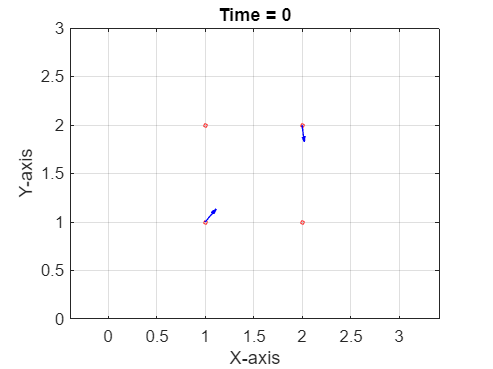


q;
vecnorm(q(1,1,:)-q(2,2,:));

figure;
% Plot the current state
cla;
plot(x(:), y(:), 'ro', 'MarkerSize', 2);  % Red dots at each grid point
hold on;
quiver(x, y, q(:,:,1), q(:,:,2), 0.25, 'b');  % Blue vectors
title(['Time = ' num2str(0)]);
xlabel('X-axis');
ylabel('Y-axis');
xlim([0,n+1]);
ylim([0,n+1]);
axis equal;
grid on;
plot_name = "turning_initial1.png";
exportgraphics(gca, plot_name);
hold off;

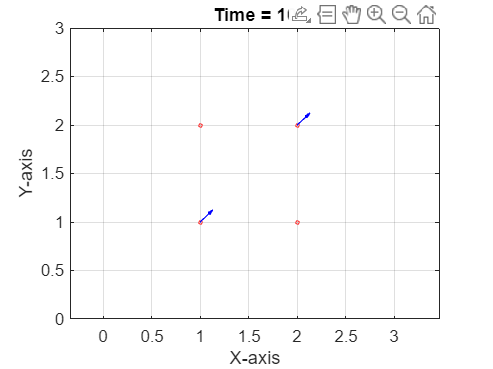


% Number of iterations
num_iterations = 200;
H = zeros(num_iterations,1);

% Main loop
for iteration = 1:num_iterations
    % Calculate turning angles for each point
    theta = get_turning(q, dt);
    theta(isnan(theta)) = 0;

    % Update vectors based on the calculated angles
    for j = 1:n
        for k = 1:n
            % Rotate the vector at point (j, k) by theta_j
            rotation_matrix = [cos(theta(j, k)), -sin(theta(j, k)); sin(theta(j, k)), cos(theta(j, k))];
            q(j, k, :) = (rotation_matrix * [q(j, k, 1); q(j, k , 2)])';
        end
    end

    idx = isnan(q);
    q(idx) = 0;
    theta_bar = 1/(n*n) * sum(sum(q));
    theta_bar = theta_bar / sqrt(sum(theta_bar.^2, 3));
    delta_theta = q - theta_bar;
    delta_theta(idx) = 0;
    delta_theta_norm = sqrt(sum(delta_theta.^2, 3));
    H(iteration) = 1/2 * sum(sum(delta_theta_norm));
    % Pause to visualize each iteration
    % pause(0.1);
end

figure;
% Plot the current state
cla;
plot(x(:), y(:), 'ro', 'MarkerSize', 2);  % Red dots at each grid point
hold on;
quiver(x, y, q(:,:,1), q(:,:,2), 0.25, 'b');  % Blue vectors
title(['Time = ' num2str(num_iterations*dt)]);
xlabel('X-axis');
ylabel('Y-axis');
xlim([0,n+1]);
ylim([0,n+1]);
axis equal;
grid on;
plot_name = "turning_final1.png";
exportgraphics(gca, plot_name);
hold off;

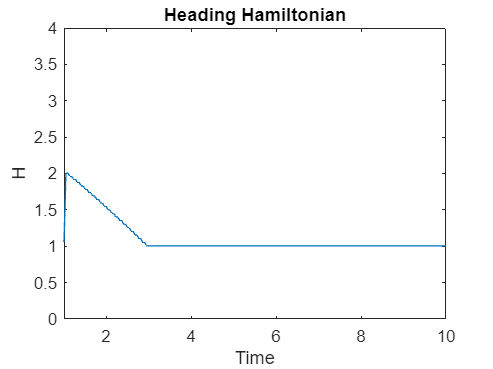


figure;

plot(linspace(1,num_iterations*dt,num_iterations)', H);
xlim([1,num_iterations*dt]);
ylim([0,n*n]);
title("Heading Hamiltonian");
xlabel("Time");
ylabel("H");
plot_name = "turning_energy1.png";
exportgraphics(gca, plot_name);

H

H =     1.0485
    2.0058
    2.0060
    1.9626
    1.9627
    1.9186
    1.9187
    1.8740
    1.8741
    1.8289


delta_theta

delta_theta = delta_theta(:,:,1) =

   -0.0033   -0.7242
   -0.7242    0.0033


delta_theta(:,:,2) =

    0.0034   -0.6896
   -0.6896   -0.0034


delta_theta_norm

delta_theta_norm =     0.0047    1.0000
    1.0000    0.0047


function theta = get_turning(q, dt)
    % Input:
    %   q: Matrix of headings (vectors) where each row represents a heading
    %   dt: Time step
    
    % Output:
    %   theta: Vector of angles by which each heading must be rotated

    % Get the number of headings
    num_headings = size(q, 1);

    % Initialize theta vector
    theta = zeros(num_headings);

    % Loop over each heading
    for j = 1:num_headings
        for k = 1:num_headings
            sum_term = 0;
            for l = 1:num_headings
                for m = 1:num_headings
                    if ~(j == l && k == m)  % Exclude the current heading (j)
                        % Compute delta and eta
                        delta = q(j,k,:) - q(l,m,:);
                        eta_jklm = atan2(delta(2) * q(j,k,1) - delta(1) * q(j,k,2), sum(delta .* q(j,k,:)));
                        if eta_jklm == 0 && sum(delta .* q(j,k,:)) < 0
                            eta_jklm = pi;
                        end
                        j;
                        k;
                        l;
                        m;
                        eta_jklm;
                        if isnan(eta_jklm)
                            eta_jklm = 0;
                        end
                        % Accumulate the sum term
                        sin(eta_jklm/2);
                        % sum_term = sum_term + sin(eta_jklm / 2)*isneighbour([j,k], [l,m], 1.1);
                        sum_term = sum_term + sin(eta_jklm / 2);
                    end
                end
            end

            % Add a navigation term, a velocity setpoint.
            p_ref = zeros(1,1,2);
            p_ref(1,1,1) = 1/sqrt(2);
            p_ref(1,1,2) = 1/sqrt(2);
            delta = q(j,k,:) - p_ref;
            eta_jk_ref = atan2(delta(2) * q(j,k,1) - delta(1) * q(j,k,2), sum(delta .* q(j,k,:)));
            sum_term = sum_term + 10*sin(eta_jk_ref / 2);

            % Compute angular velocity omega_j for the current heading (j)
            B = 1;
            omega_jk = tanh(B * sum_term);
    
            % Compute theta_j as omega_j * dt
            theta(j,k) = -omega_jk * dt;

        end
    end
end

function out = isneighbour(pos1, pos2, r)
    if vecnorm(pos1-pos2, 2, 2) <= r
        out = 1;
    else
        out = 0;
    end
end
